clear, syms s t

G   = tf(2, [1 0.5]);
Gd  = tf(2.5, [1 0.5]);

% 1.b) resposta do sistema com porta fechada e temperatura inicial 0 °C
    step(G*5)
    title('Resposta a um degrau de amplitude 5')
    ylim([0 25])

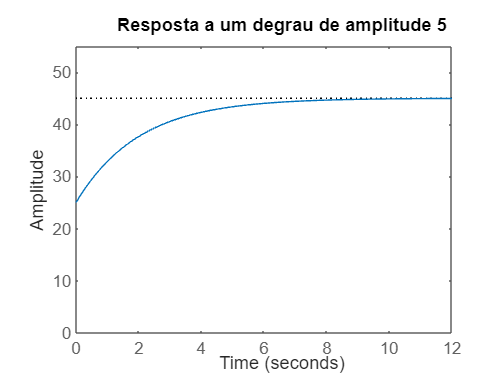

% 1.c) resposta do sistema com porta fechada e temperatura inicial 25 °C
    X0 = 25;
    step(G*5 + X0)
    title('Resposta do sistema')
    ylim([0 55])

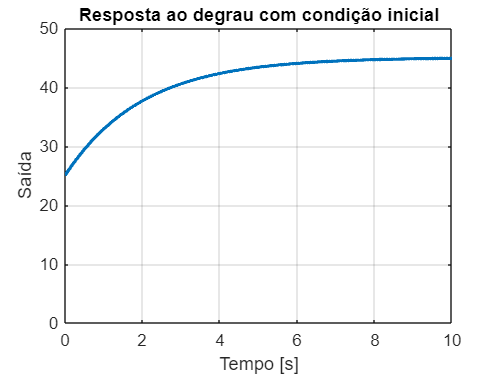

% 1.d)
    U = tf(5, [1 0]);
    Ud = tf([1], [1 0], 'InputDelay', 2);
    X0 = 25;
    
    t = 0: 0.01:10;
    
    [y_t, t] = impulse(G*U, t);
    y_t = y_t + X0;

    figure;
    plot(t, y_t, 'LineWidth', 2);
    grid on;
    xlabel('Tempo [s]');
    ylabel('Saída');
    title('Resposta ao degrau com condição inicial');
    xlim([0 10]);
    ylim([0 50]); % Ajuste conforme necessário